# WorkSheet 12

Problem 1

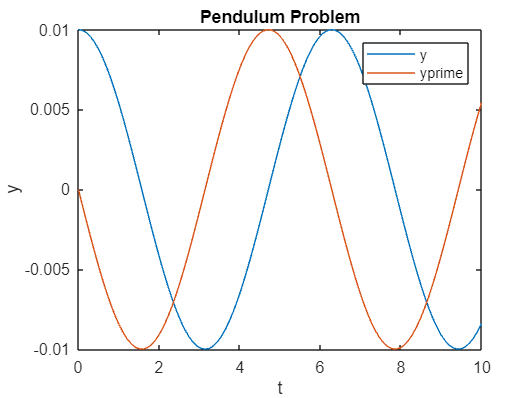

% part 1
f = @(t,y) [y(2); -sin(y(1))];
tspan = linspace(0,10,100);
ic = [0.01,0];
[t1,Y1] = ode45(f,tspan,ic);
y1 = Y1(:,1);
y1p = Y1(:,2);
figure
plot(t1,y1);
hold on
plot(t1,y1p);
xlabel('t');
ylabel ('y');
legend('y', 'yprime');
title('Pendulum Problem');

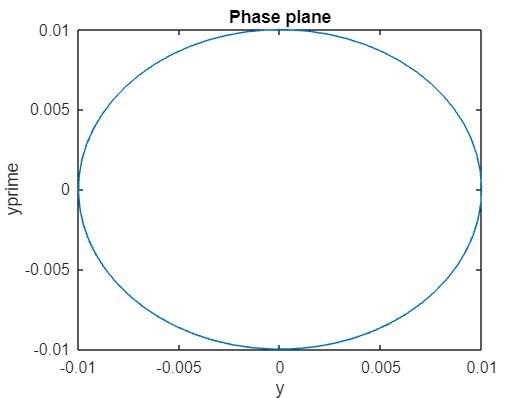

% phase plane
figure
plot(y1,y1p);
xlabel('y');
ylabel('yprime');
title('Phase plane');

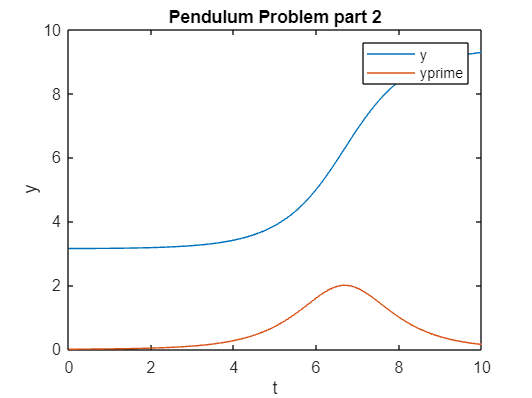


% part 2
ic = [pi()+.01,0];
f = @(t,y) [y(2); -sin(y(1))];
tspan = linspace(0,10,100);
[t2,Y2] = ode45(f,tspan,ic);
y2 = Y2(:,1);
y2p = Y2(:,2);
figure
plot (t2,y2);
hold on
plot(t2, y2p);
xlabel('t');
ylabel('y');
legend ('y', 'yprime');
title('Pendulum Problem part 2');

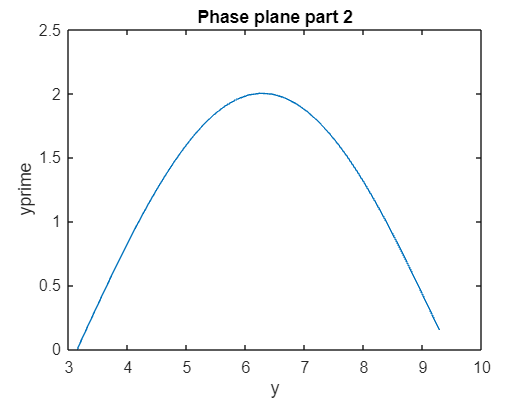

% Phase plane
figure 
plot(y2,y2p);
xlabel('y');
ylabel('yprime');
title('Phase plane part 2')

Problem 2

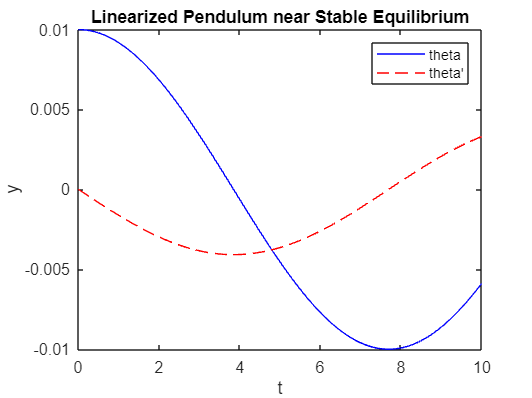

% Part 1
f = @(t,y) [y(2); -(y(1)-(y(1)^3))/6];
tspan = linspace(0,10,100);
y0 = [0.01, 0];
[t, y] = ode45(f, tspan, y0);
figure
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
xlabel('t');
ylabel('y');
legend('theta', 'theta''');
title('Linearized Pendulum near Stable Equilibrium');

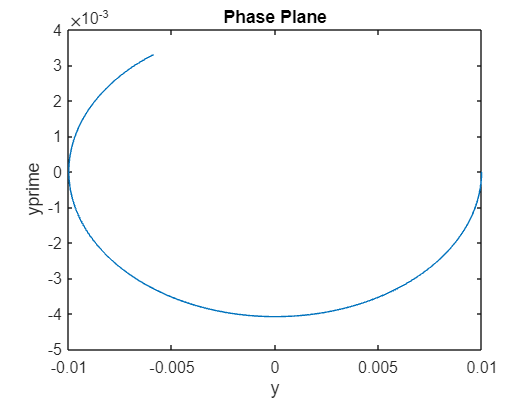

% Phase Plane
figure 
plot(y(:,1), y(:,2));
xlabel('y');
ylabel('yprime');
title('Phase Plane');

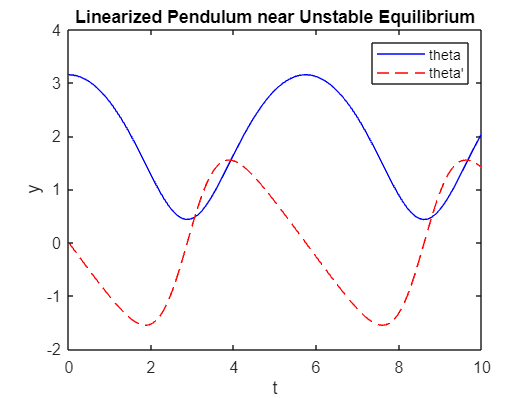

% Part 2
f = @(t,y) [y(2); -((y(1)+pi)-(-y(1)+pi)^3)/6];
tspan = linspace(0,10,100);
y0 = [pi + 0.01, 0];
[t, y2] = ode45(f, tspan, y0);
figure
plot(t, y2(:,1), 'b', t, y2(:,2), 'r--');
xlabel('t');
ylabel('y');
legend('theta', 'theta''');
title('Linearized Pendulum near Unstable Equilibrium');

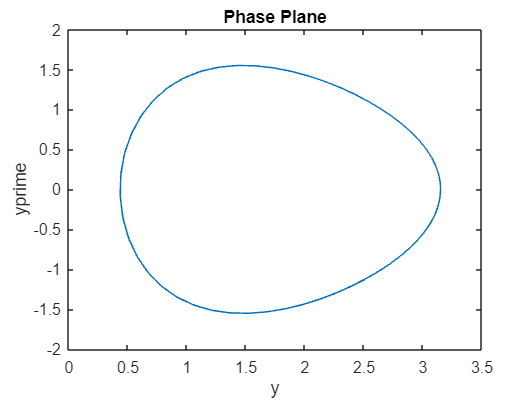

% Phase Plane
figure 
plot(y2(:,1), y2(:,2));
xlabel('y');
ylabel('yprime');
title('Phase Plane');

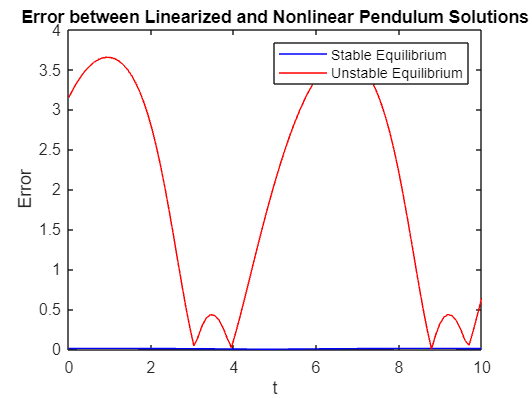


% Part 3
% Part 3: Plot Error
error_stable = abs(y(:,1) - y(:,2));
error_unstable = abs(y2(:,1) - y2(:,2));

figure
plot(t, error_stable, 'b', t, error_unstable, 'r')
xlabel('t')
ylabel('Error')
legend('Stable Equilibrium', 'Unstable Equilibrium')
title('Error between Linearized and Nonlinear Pendulum Solutions')

Problem 2 (alternate way was confused on what appoach but use the above)

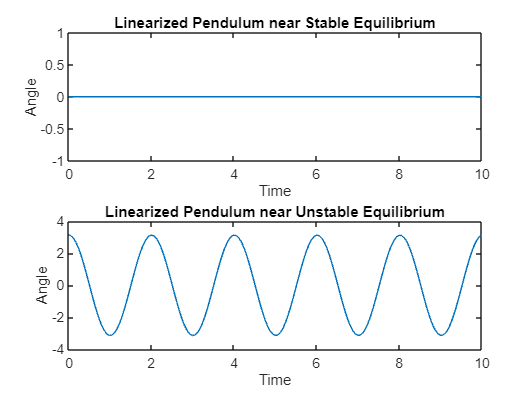

% Parameters
g = 9.81; % acceleration due to gravity
L = 1; % length of the pendulum
theta0 = 0; % initial angle
omega0 = 0; % initial angular velocity

% Define the ODE function
ode = @(t, y) [y(2); -g/L * y(1)];

% Solve the ODE near stable equilibrium
[t_stable, y_stable] = ode45(ode, [0 10], [theta0, omega0]);

% Solve the ODE near unstable equilibrium
[t_unstable, y_unstable] = ode45(ode, [0 10], [pi, omega0]);

% Plot the solutions
figure;
subplot(2, 1, 1);
plot(t_stable, y_stable(:, 1));
xlabel('Time');
ylabel('Angle');
title('Linearized Pendulum near Stable Equilibrium');

subplot(2, 1, 2);
plot(t_unstable, y_unstable(:, 1));
xlabel('Time');
ylabel('Angle');
title('Linearized Pendulum near Unstable Equilibrium');

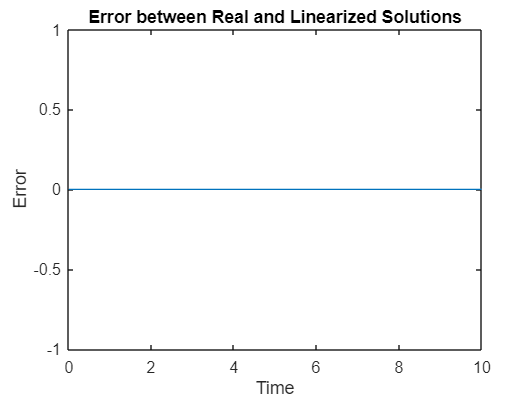


% Part 3
[t_real, y_real] = ode45(ode, [0 10], [theta0, omega0]);
figure;
plot(t_real, abs(y_real(:, 1) - y_stable(:, 1)));
xlabel('Time');
ylabel('Error');
title('Error between Real and Linearized Solutions');

Problem 3

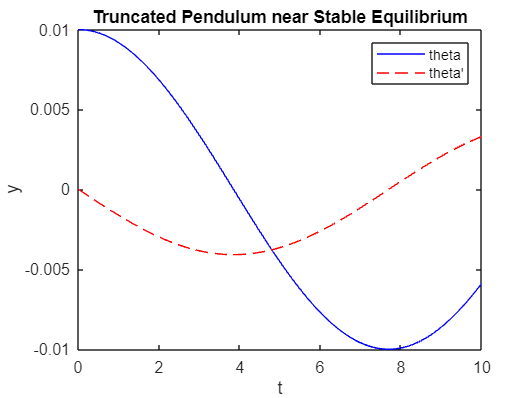

import matlab.ode.*
% Part 1
f = @(t,y) [y(2); -(y(1)-(y(1)^3)+(y(1)^5)/120)/6];
tspan = linspace(0,10,100);
y0 = [0.01, 0];
[t, y] = ode45(f, tspan, y0);
figure
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
xlabel('t');
ylabel('y');
legend('theta', 'theta''');
title('Truncated Pendulum near Stable Equilibrium');

% Phase Plane
figure 
plot(y(:,1), y(:,2));
xlabel('y');
ylabel('yprime');
title('Phase Plane');

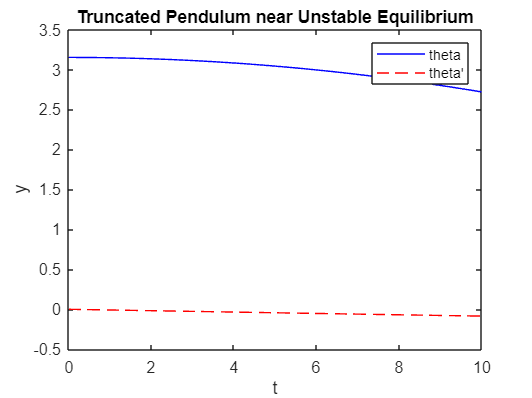


% Part 2
f = @(t,y) [y(2); -((y(1)+pi)-(-y(1)+pi)^3+(y(1)-pi)^5)/120/6];
tspan = linspace(0,10,100);
y0 = [pi + 0.01, 0];
[t, y2] = ode45(f, tspan, y0);
figure
plot(t, y2(:,1), 'b', t, y2(:,2), 'r--');
xlabel('t');
ylabel('y');
legend('theta', 'theta''');
title('Truncated Pendulum near Unstable Equilibrium');

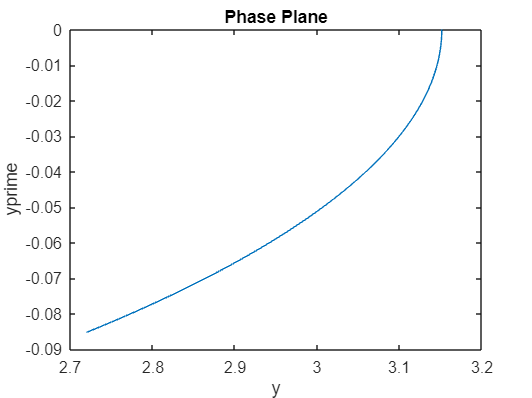

% Phase Plane
figure 
plot(y2(:,1), y2(:,2));
xlabel('y');
ylabel('yprime');
title('Phase Plane');


% Part 3
error_stable = abs(y(:,1) - y(:,2));
error_unstable = abs(y2(:,1) - y2(:,2));
figure
plot(t, error_stable)
hold on 
plot(t,error_unstable)
xlabel('t')
ylabel('Error')
title('Error between Truncated and Nonlinear Pendulum near Stable and Unstable Equilibrium')

Problem 4

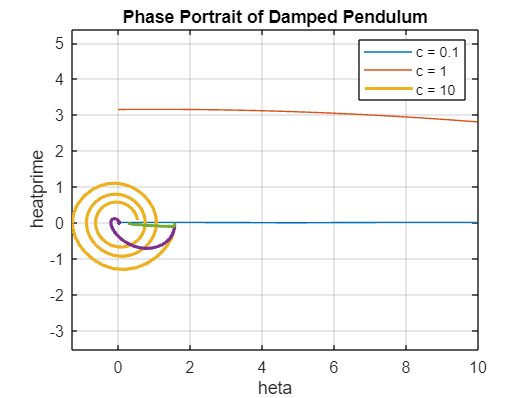

% Parameters
c = [0.1, 1, 10];
tspan = [0, 20];
y0 = [pi/2, 0];

% Solve damped pendulum equation for different values of c
for i = 1:length(c)
    f = @(t,y) [y(2); -c(i)*y(2) - sin(y(1))];
    [t, y] = ode45(f, tspan, y0);
    plot(y(:,1), y(:,2), 'LineWidth', 2);
    hold on;
end

% Plot phase portrait
xlabel('theta');
ylabel('thetaprime');
title('Phase Portrait of Damped Pendulum');
axis equal;
grid on;
legend('c = 0.1', 'c = 1', 'c = 10', 'Location', 'Best');
hold off;